#### **Paingen as reference**

link_density = "0.3"

link_density = "0.3"

load(sprintf("Data/paingen as ref/240326_HDI_res_paingen_%s.mat", link_density))
load(sprintf("Data/paingen as ref/240401_paingen_metrics_%s.mat", link_density))
% writetable(bs.HDIs.regions, sprintf('Data/HDI_res_paingen_%s.csv', link_density))

metrics = {'degree', 'betweenness_bin', 'clustercoef_bin', 'local_efficiency_bin', 'eigenvector_centrality_bin'};
% subset metrics in CBP patients & HC
metrics_CBP = bs.graph_properties.regions(bs.subject_metadata.is_patient, metrics)

metrics_CBP = 286×5 table
       degree       betweenness_bin    clustercoef_bin    local_efficiency_bin    eigenvector_centrality_bin
    ____________    _______________    _______________    ____________________    __________________________

    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       

metrics_HC = bs.graph_properties.regions(~bs.subject_metadata.is_patient, metrics)

metrics_HC = 51×5 table
       degree       betweenness_bin    clustercoef_bin    local_efficiency_bin    eigenvector_centrality_bin
    ____________    _______________    _______________    ____________________    __________________________

    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×

% get average metrics per node in reference group
metrics_ref_avg = mean(bs_paingen.graph_properties.regions)

metrics_ref_avg = 1×9 table
     community         core_w       eigenvector_centrality_bin       degree       betweenness_bin    clustercoef_bin    local_efficiency_bin    trans_bu    glob_efficiency
    ____________    ____________    __________________________    ____________    _______________    _______________    ____________________    ________    _______________

    1×489 double    1×489 double           1×489 double           1×489 double     1×489 double       1×489 double          1×489 double        0.53179         0.64862    


% subtract reference from CBP patients & HC
metrics_CBP_ref_subtr = metrics_CBP - metrics_ref_avg(:, metrics)

metrics_CBP_ref_subtr = 286×5 table
       degree       betweenness_bin    clustercoef_bin    local_efficiency_bin    eigenvector_centrality_bin
    ____________    _______________    _______________    ____________________    __________________________

    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 dou

metrics_HC_ref_subtr = metrics_HC - metrics_ref_avg(:, metrics)

metrics_HC_ref_subtr = 51×5 table
       degree       betweenness_bin    clustercoef_bin    local_efficiency_bin    eigenvector_centrality_bin
    ____________    _______________    _______________    ____________________    __________________________

    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 doubl



which_metric = "betweenness_bin"

which_metric = "clustercoef_bin"

% in each metric, transpose nodal metric values in each patient (nodes as index, their values in another column)
% concatenate patients vertically
slope_plot_arr = double.empty;
for patient_idx = 1:286
    per_arr = metrics_CBP_ref_subtr{patient_idx, which_metric}';
    slope_plot_arr = vertcat(slope_plot_arr, per_arr);
end

% same for healthies
slope_plot_arr_HC = double.empty;
for idx = 1:51
    per_arr = metrics_HC_ref_subtr{idx, which_metric}';
    slope_plot_arr_HC = vertcat(slope_plot_arr_HC, per_arr);
end

% average reference metrics are replicated by the number of patients (489 nodes * number of patients) and
% merged in as a new column
metrics_ref_avg_long = repmat(metrics_ref_avg{1, which_metric}', 286, 1);
slope_plot_arr = [slope_plot_arr, metrics_ref_avg_long];
% too much data to plot - randomly sample 5000 nodes from dataset, across
% all patients
k = randperm(height(slope_plot_arr));
CBP_slope = slope_plot_arr(k(1:5000),:);

% same for healthies
metrics_ref_avg_long = repmat(metrics_ref_avg{1, which_metric}', 51, 1);
slope_plot_arr_HC = [slope_plot_arr_HC, metrics_ref_avg_long];
k = randperm(height(slope_plot_arr_HC));
HC_slope = slope_plot_arr_HC(k(1:5000),:);


% plot
plot_correlation(CBP_slope(:, 1), CBP_slope(:, 2), 'colors', {'bo'})

OLS  partial r: 0.00, b = 0.00, se = 0.01, t(4998) = 0.23, p = 0.8163, d = 0.00


ans = 1×1 cell array
    {1×5001 Line}


plot_correlation(HC_slope(:, 1), HC_slope(:, 2), 'colors', {'ro'}, 'ylabel', 'group - Paingen ref', 'xlabel', 'Paingen ref'); title(which_metric)

OLS  partial r: 0.05, b = 0.03, se = 0.01, t(4998) = 3.88, p = 0.0001, d = 0.05


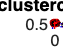

txt = 'red=HC blue=CBP';
text(median(CBP_slope(:, 2)), min(CBP_slope(:, 2)), txt)
saveas(gcf, 'Graphs/paingen_slope_HDI_' + which_metric + '_' + link_density + '.png')

#### **Healthy Controls as reference group**

link_density = "0.3"

link_density = "0.3"

load(sprintf("Data/CV HC as ref/240322_HDI_res_ctrlCV_%s.mat", link_density))
% writetable(bs.HDIs.regions, sprintf('Data/HDI_res_paingen_%s.csv', link_density))

metrics = {'degree', 'betweenness_bin', 'clustercoef_bin', 'local_efficiency_bin', 'eigenvector_centrality_bin'};
% subset metrics in CBP patients & HC
metrics_CBP = bs.graph_properties.regions(bs.subject_metadata.is_patient, metrics)

metrics_CBP = 286×5 table
       degree       betweenness_bin    clustercoef_bin    local_efficiency_bin    eigenvector_centrality_bin
    ____________    _______________    _______________    ____________________    __________________________

    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       

metrics_HC = bs.graph_properties.regions(~bs.subject_metadata.is_patient, metrics)

metrics_HC = 51×5 table
       degree       betweenness_bin    clustercoef_bin    local_efficiency_bin    eigenvector_centrality_bin
    ____________    _______________    _______________    ____________________    __________________________

    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×

% get average metrics per node in reference group (HC!)
metrics_ref_avg = mean(metrics_HC)

metrics_ref_avg = 1×5 table
       degree       betweenness_bin    clustercoef_bin    local_efficiency_bin    eigenvector_centrality_bin
    ____________    _______________    _______________    ____________________    __________________________

    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       



% subtract reference (HC) from CBP patients & HC
metrics_CBP_ref_subtr = metrics_CBP - metrics_ref_avg(:, metrics)

metrics_CBP_ref_subtr = 286×5 table
       degree       betweenness_bin    clustercoef_bin    local_efficiency_bin    eigenvector_centrality_bin
    ____________    _______________    _______________    ____________________    __________________________

    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 dou

metrics_HC_ref_subtr = metrics_HC - metrics_ref_avg(:, metrics)

metrics_HC_ref_subtr = 51×5 table
       degree       betweenness_bin    clustercoef_bin    local_efficiency_bin    eigenvector_centrality_bin
    ____________    _______________    _______________    ____________________    __________________________

    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 double       1×489 double          1×489 double               1×489 double       
    1×489 double     1×489 doubl


which_metric = "betweenness_bin"

which_metric = "clustercoef_bin"

% in each metric, transpose nodal metric values in each patient (nodes as index, their values in another column)
% concatenate patients vertically
slope_plot_arr = double.empty;
for patient_idx = 1:height(metrics_CBP_ref_subtr)
    per_arr = metrics_CBP_ref_subtr{patient_idx, which_metric}';
    slope_plot_arr = vertcat(slope_plot_arr, per_arr);
end

% same for healthies
slope_plot_arr_HC = double.empty;
for idx = 1:height(metrics_HC_ref_subtr)
    per_arr = metrics_HC_ref_subtr{idx, which_metric}';
    slope_plot_arr_HC = vertcat(slope_plot_arr_HC, per_arr);
end

% average reference metrics are replicated by the number of patients (489 nodes * number of patients) and
% merged in as a new column
metrics_ref_avg_long = repmat(metrics_ref_avg{1, which_metric}', 286, 1);
slope_plot_arr = [slope_plot_arr, metrics_ref_avg_long];
% too much data to plot - randomly sample 5000 nodes from dataset, across
% all patients
k = randperm(height(slope_plot_arr));
CBP_slope = slope_plot_arr(k(1:5000),:);

% same for healthies
metrics_ref_avg_long = repmat(metrics_ref_avg{1, which_metric}', 51, 1);
slope_plot_arr_HC = [slope_plot_arr_HC, metrics_ref_avg_long];
k = randperm(height(slope_plot_arr_HC));
HC_slope = slope_plot_arr_HC(k(1:5000),:);


% plot
plot_correlation(CBP_slope(:, 1), CBP_slope(:, 2), 'colors', {'bo'})

OLS  partial r: -0.05, b = -0.03, se = 0.01, t(4998) = -3.61, p = 0.0003, d = -0.05


ans = 1×1 cell array
    {1×5001 Line}


plot_correlation(HC_slope(:, 1), HC_slope(:, 2), 'colors', {'ro'}, 'ylabel', 'group - CV HC ref', 'xlabel', 'CV HC ref'); title(which_metric)

OLS  partial r: -0.02, b = -0.01, se = 0.01, t(4998) = -1.24, p = 0.2153, d = -0.02


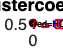

txt = 'red=HC blue=CBP ';
text(median(CBP_slope(:, 2)), min(CBP_slope(:, 2)), txt)
saveas(gcf, 'Graphs/CV_HC_slope_HDI_' + which_metric + '_' + link_density + '.png')